# FormulaBuckeyes IC 2023

clf;
% MODES
GTYPE = "C185";      % Switches the accelerometer used for calculations
SPEEDMODE = "GPS";  % Switches the speed data used for calculations
DATATYPE = "LapsBeacon";   % Changes the lap finding and run trimming behavior 
DRIVER = "Colin";

% IMPORT
addpath("./Functions/");
if exist("run", "var") ~= 1
    [filename, path] = uigetfile('*.csv', 'Select First MoTeC Output File');
    run = motecImport(filename, path);
end

% TRIM
if DATATYPE == "LapsBeacon"
    li = find(run.LapNumber > min(run.LapNumber) & run.LapNumber < max(run.LapNumber));
    run = run(li,:); % trim the original run variable
end

% HELPER VARIABLES 
[gLat, gLong, speed, time] = SetupVariables(run, GTYPE, SPEEDMODE);
car = FB2223();
lapZero = min(run.LapNumber) - 1; 
lapMax = max(run.LapNumber);

startDate = num2str(run.GPSDate(1));
startTime = num2str(run.GPSTime(1));
rundate = sprintf("%s/%s/%s %s:%s",startDate(3:4),startDate(1:2),startDate(5:6),startTime(1:2),startTime(3:4));
% Understanding Date/Time data: https://www.fia.com/sites/default/files/adr.002.20_user_manual.pdf

## Endurance Summary Sheet

fprintf("Run Date: %s",rundate)

Run Date: 05/20/23 18:24

fprintf("Report Generated: %s", datetime("now"))

Report Generated: 05-Oct-2023 20:15:56

fprintf("Driver: %s", DRIVER)

Driver: Colin

### Track Map

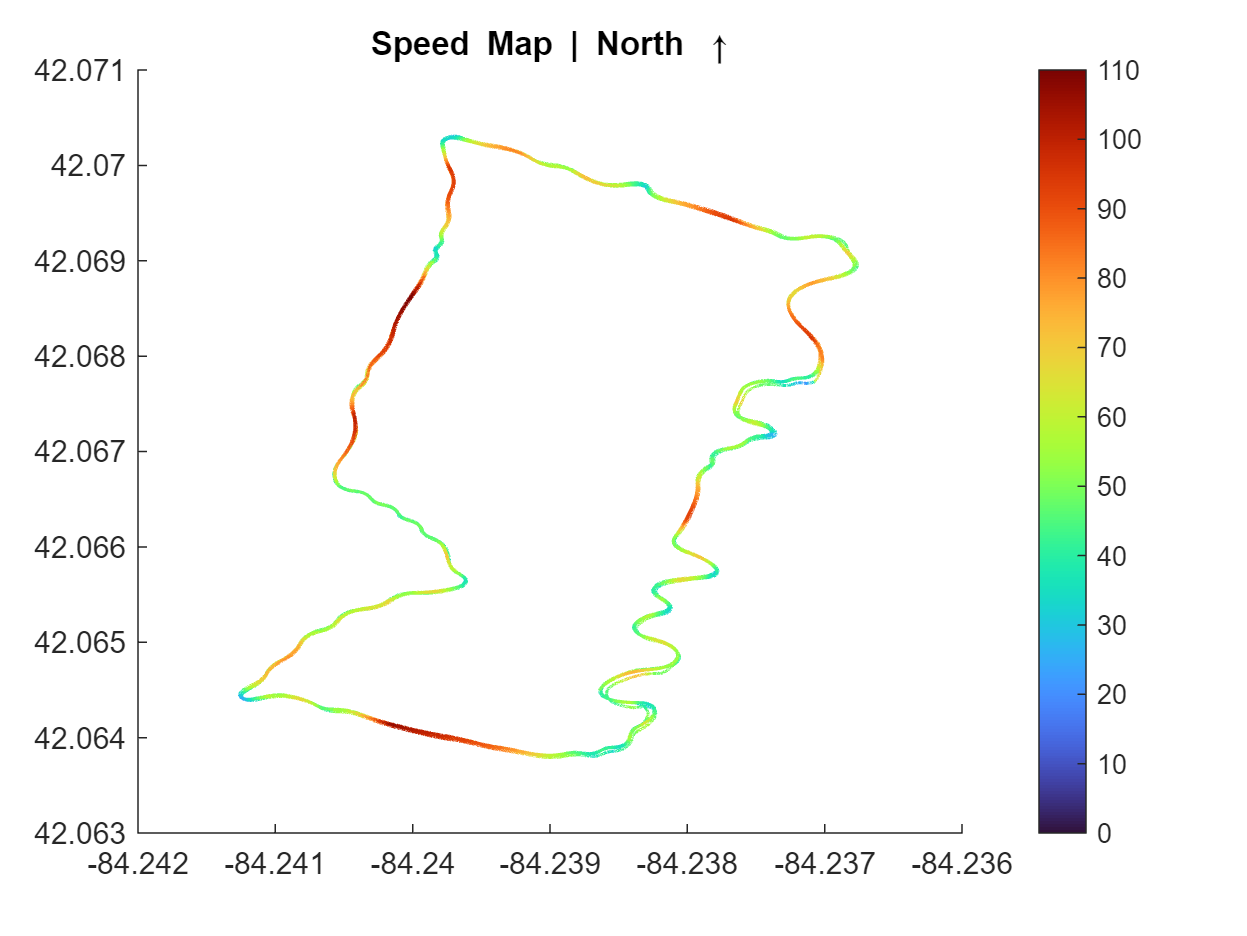

figure 
TrackDisplay(run.GPSLongitude, run.GPSLatitude, speed)
title("Speed Map | North \uparrow")

### Table

[UA, AA, WA] = UndersteerAngle(gLat,speed,run.SteeredAngle,car);

[TA, gMaxes, gThrottles] = ThrottleAcceptance(run, gLat); 

for i = 1:lapMax-lapZero
    [i1, i2] = LapBounds(run, lapZero, lapMax, i);
    
    Lap(i) = i;
    lapTimes(i) = time(i2) - time(i1);
    
    [UA1, AA1, WA1] = UndersteerAngle(gLat(i1:i2),speed(i1:i2),run.SteeredAngle(i1:i2),car);
    avgUA(i) = mean(UA1);

    gLatMaxes(i) = max(gLat(i1:i2));
    gLatMins(i) = min(gLat(i1:i2));
    
    [GO, GB, GA, GC, GAero] = GripSubsets(gLat(i1:i2), gLong(i1:i2), speed(i1:i2));
    avgGO(i) = mean(GO);
    avgGB(i) = mean(abs(GB));
    avgGA(i) = mean(GA);
    avgGC(i) = mean(GC);
    avgGAero(i) = mean(GAero);
end

OverallGrips = GripSubsets(gLat, gLong, speed);

summaryTable = table(Lap',lapTimes',gLatMaxes',gLatMins',avgUA',avgGO',avgGB',avgGA',avgGC',avgGAero', ...
    'VariableNames',["Lap #" "Lap Time" "gLat Max" "gLat Min", "Avg Understeer Angle" ...
    "Avg Overall Grip" "Avg Braking G" "Avg Accel G" "Avg Cornering G" "Avg Aero G"]);
disp(summaryTable)

    Lap #    Lap Time    gLat Max    gLat Min    Avg Understeer Angle    Avg Overall Grip    Avg Braking G    Avg Accel G    Avg Cornering G    Avg Aero G
    _____    ________    ________    ________    ____________________    ________________    _____________    ___________    _______________    __________

      1        133         2.45       -2.24             4.1789                1.3081            1.0674          1.1278            1.0626          1.1278  
      2        138         2.09       -2.09              3.397                 1.278             1.099          1.0963            1.0107          1.0963  
      3        131         2.12        

### Graphs

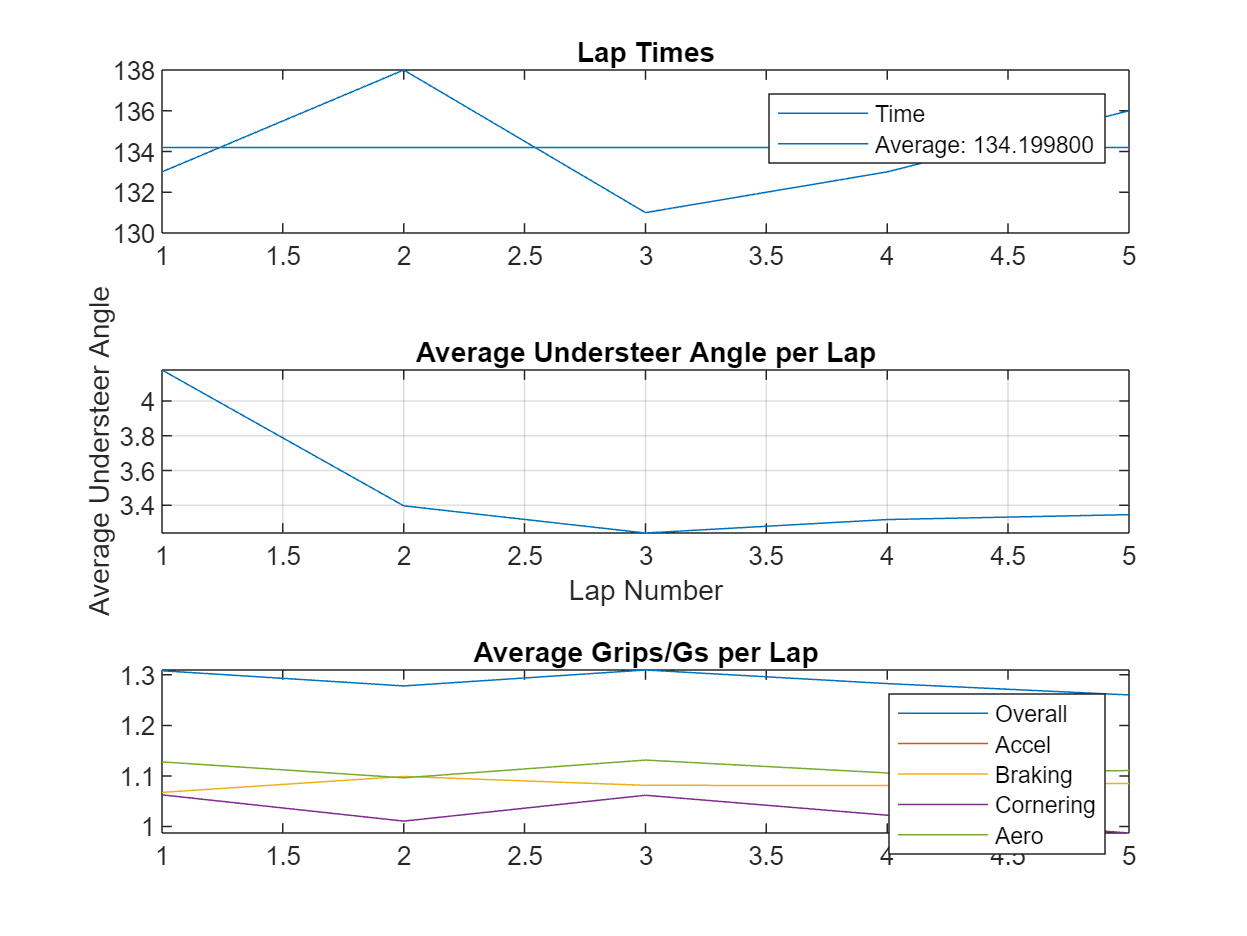

figure
tiledlayout(3,1)

nexttile
plot(Lap,lapTimes)
title("Lap Times")
line([1 max(Lap)], [mean(lapTimes) mean(lapTimes)])
legend('Time', sprintf('Average: %f', mean(lapTimes)))

nexttile
plot(Lap, avgUA); grid on; title('Average Understeer Angle per Lap'); 
xlabel('Lap Number'); ylabel('Average Understeer Angle')

nexttile
plot(Lap, avgGO, ...
    Lap, avgGA, ...
    Lap, avgGB, ...
    Lap, avgGC, ...
    Lap, avgGAero)
title("Average Grips/Gs per Lap")
legend('Overall','Accel','Braking','Cornering','Aero')

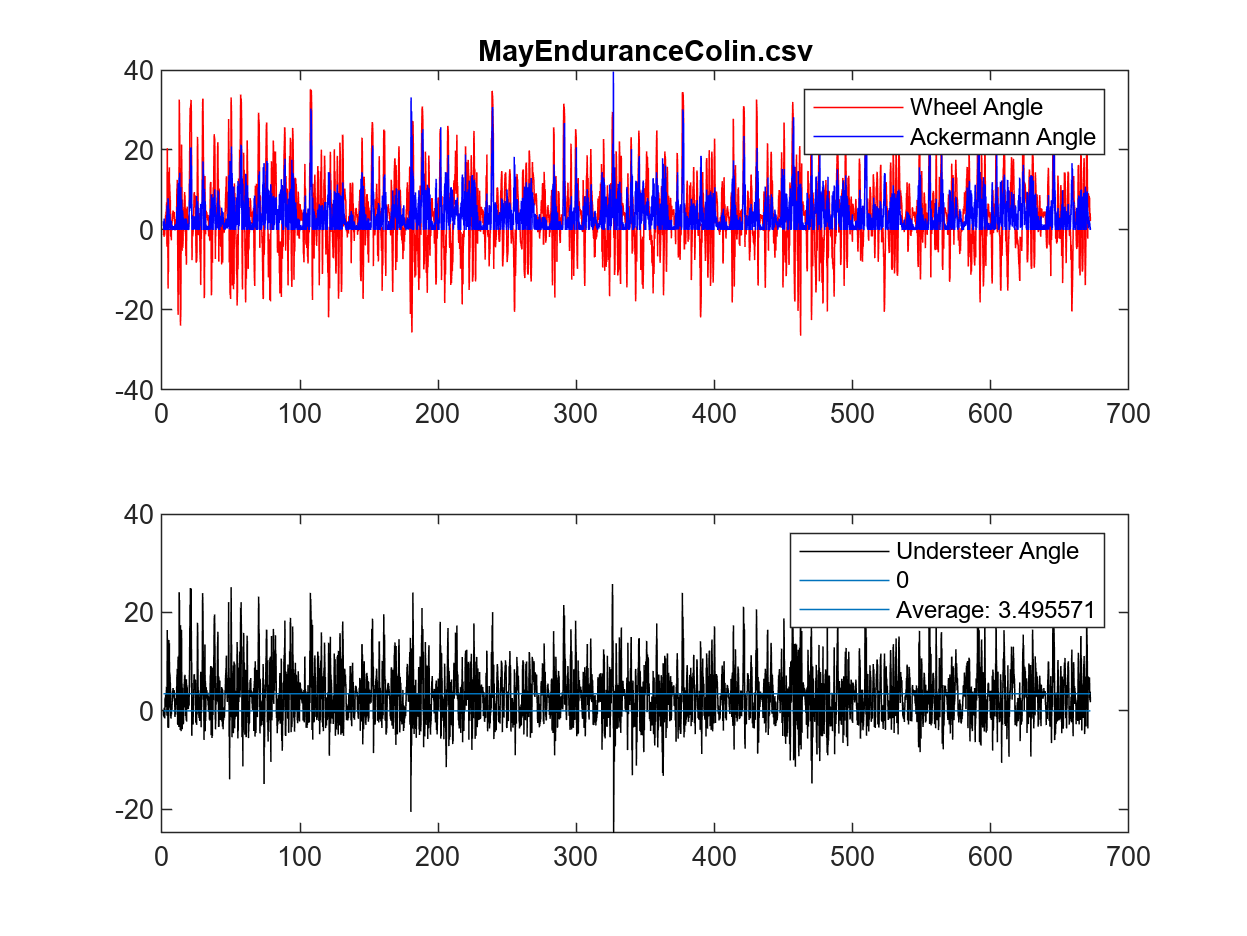

figure
UndersteerDisplay(filename, time, WA, AA, UA);

%% File Output
outputFile = "./html/EnduranceSummary.html";
if exist(outputFile, 'file') ; delete(outputFile); end
web(export('SummaryEndurance.mlx',outputFile,HideCode=true));